clearvars; close all; clc;

% Load file information
folder_path = 'D:\Dropbox\Data\7-29-20 neurons glut4 and actin\utrophin\';
cd(folder_path);
ruler_name = 'cell_1_area_1_dz_20_r_scan.tif';
image_name ='cell_1_area_1_dz_10_r_0.tif';
ruler_image = readtiff(ruler_name);
image = readtiff(image_name);

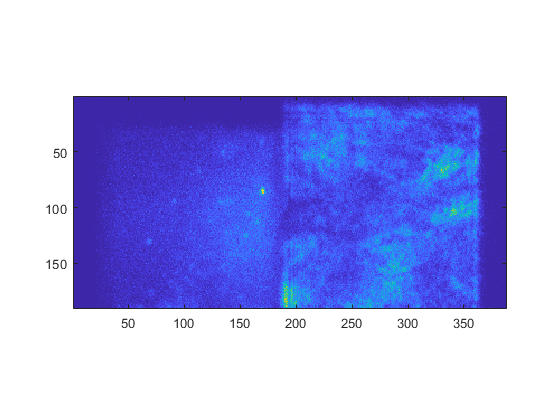

%Visualize Information
imagesc(ruler_image(:,:,1))
axis image

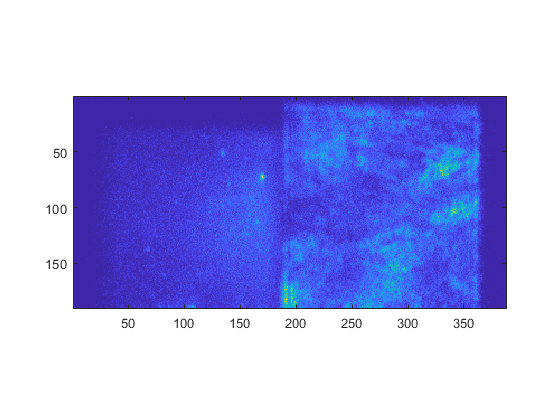

imagesc(ruler_image(:,:,2))
axis image

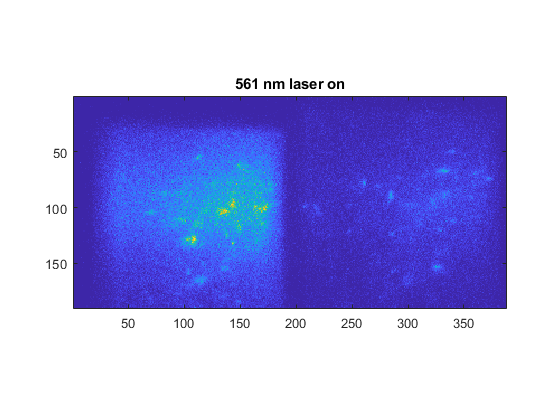


imagesc(image(:,:,1))
axis image
title('561 nm laser on')

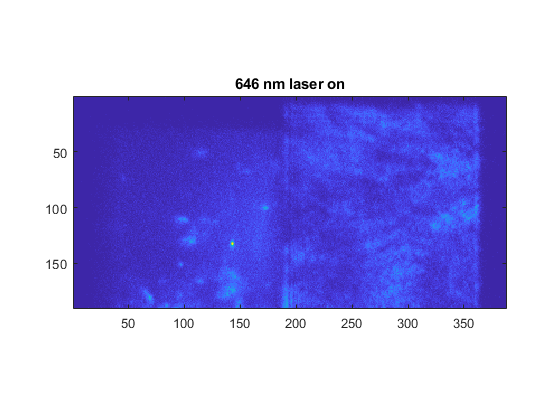

imagesc(image(:,:,2))
title('646 nm laser on')
axis image

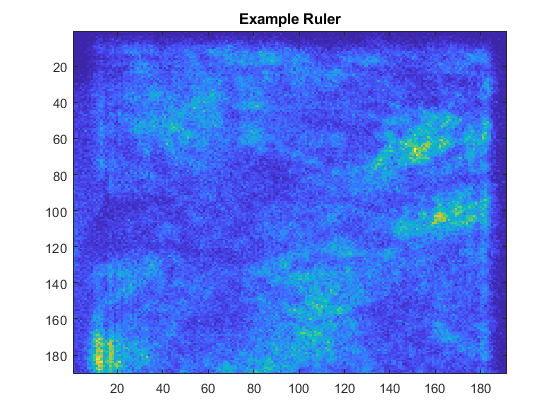


channel_split = 180; % X position split in pixels
channel_split_end = 370; % end of channel cropping
imagesc(ruler_image(:,channel_split:channel_split_end,1))
title('Example Ruler')

sub_ruler_image = ruler_image(:,channel_split:channel_split_end,:);

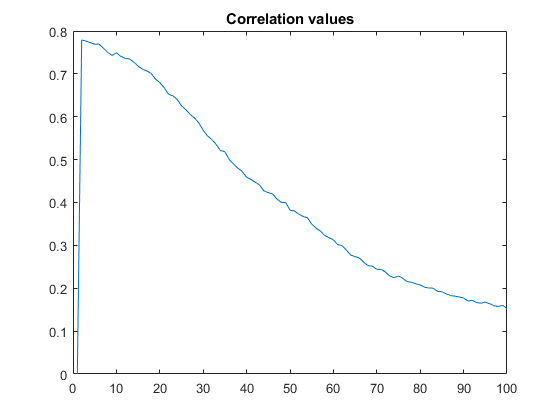

% Build ruler for subsequent measurment
[m,n,o] = size(sub_ruler_image);

C = zeros(o,1);
for i = 2:o
    C(i) = corr2(sub_ruler_image(:,:,1),sub_ruler_image(:,:,i));
end
plot(C)
title("Correlation values")

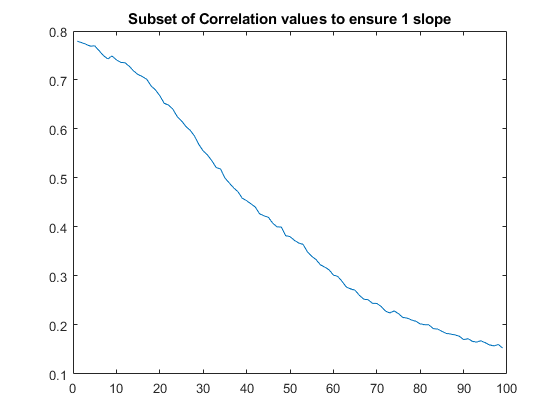

sub_C  = C(2:end);
max_corr = find(sub_C == max(sub_C));
min_corr = find(sub_C == min(sub_C));
plot(C(2:end));
title('Subset of Correlation values to ensure 1 slope')

ruler = sub_ruler_image(:,:,1:end);

% Parse image data to grab laser_sections
% Remember red channel is the even frames
laser_images = image(:,channel_split:channel_split_end,2:2:end);

indexes2 = get_index_from_ruler(ruler,laser_images); 

indexes3 = four_piece_ruler(ruler,laser_images);
indexe4 = get_index_from_blurred_ruler(ruler, laser_images);

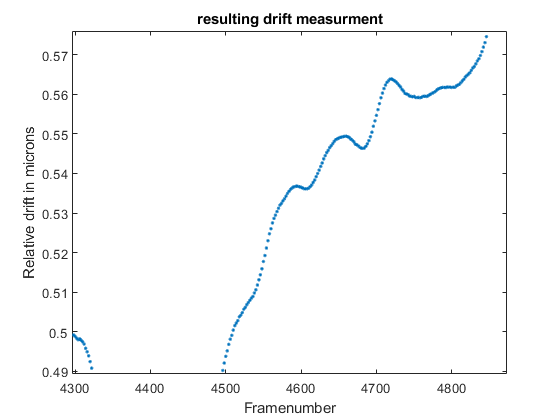

indexes = indexes3;

% Visualize the result
step_size = 0.02;
plot((1:numel(indexes))*2,gausssmooth(indexes*step_size, 5,10), '.')
hold on
plot([5250 5600, 5600, 5250, 5250], [0.55,0.55, 0.65,0.65,0.55] ,'r')
hold off
title("resulting drift measurment")
xlabel('Framenumber')
ylabel('Relative drift in microns')

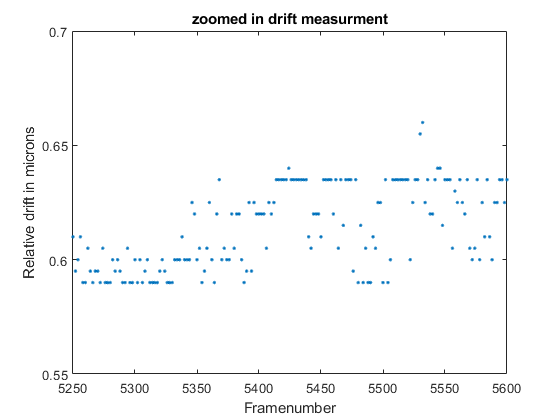


% Visualize the result
plot((1:numel(indexes))*2,indexes*step_size, '.')
xlim([5250 5600])
ylim([0.55 0.7])
title("zoomed in drift measurment")
xlabel('Framenumber')
ylabel('Relative drift in microns')

% Try spline building of scope
frames = 1:numel(image(1,1,:));
adjustment = interp1(1:numel(indexes), indexes, frames)* step_size;
plot(frames, adjustment)

function indexes = get_index_from_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C = [];
        for j = 1:r
           C(j) = corr2(ruler(:,:,j), image_stack(:,:,i));  
        end
        indexes(i) = find(C == max(C));
    end
end

function indexes = get_index_from_blurred_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C = [];
        image_to_compare = imgaussfilt(image_stack(:,:,i),2);
        for j = 1:r
            blurred_ruler = imgaussfilt(ruler(:,:,j),2);
           C(j) = corr2(blurred_ruler, image_to_compare);  
        end
        indexes(i) = find(C == max(C));
    end
end

function indexes = four_piece_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C1 = [];
        C2 = [];
        C3 = [];
        C4 = [];
        image_to_compare = imgaussfilt(image_stack(:,:,i),1.5);
        for j = 1:r
            % Split the correlation into quadrants
            blurred_ruler = imgaussfilt(ruler(:,:,j),1.5);
           C1(j) = corr2(blurred_ruler(1:round(m/2),1:round(n/2)), image_to_compare(1:round(m/2),1:round(n/2)));
           C2(j) = corr2(blurred_ruler(round(m/2):end,1:round(n/2)), image_to_compare(round(m/2):end,1:round(n/2)));
           C3(j) = corr2(blurred_ruler(1:round(m/2),round(n/2):end), image_to_compare(1:round(m/2),round(n/2):end));
           C4(j) = corr2(blurred_ruler(round(m/2):end,round(n/2):end), image_to_compare(round(m/2):end,round(n/2):end));
        end
        index_1 = find(C1 == max(C1));
        index_2 = find(C2 == max(C2));
        index_3 = find(C3 == max(C3));
        index_4 = find(C4 == max(C4));
        
        indexes(i) = (index_1 + index_2 + index_3 + index_4)/4;
    end
end
    

